## matlab机器学习基础

山东理工大学 数学院  周世祥 shixiangbupt@qq.com

## 本节开始学习matlab基本的数据存取操作

2017版本以上，统计机器学习工具箱：

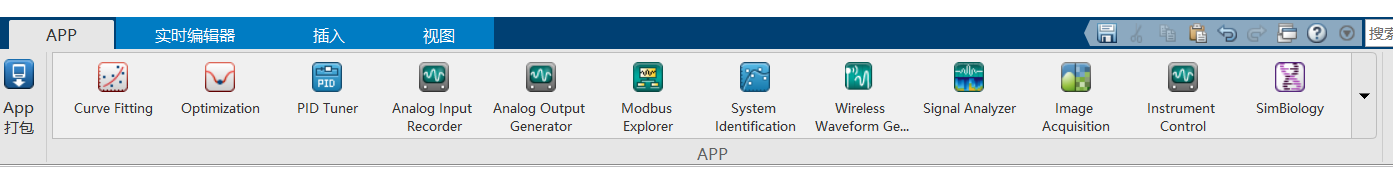

丰富的函数算法库，完善的APP，交互式界面

聚类clustering,

分类 classification

回归 regression

神经网络 neural  network  app

曲线拟合 curve fitting app

分类器 classification  learner app

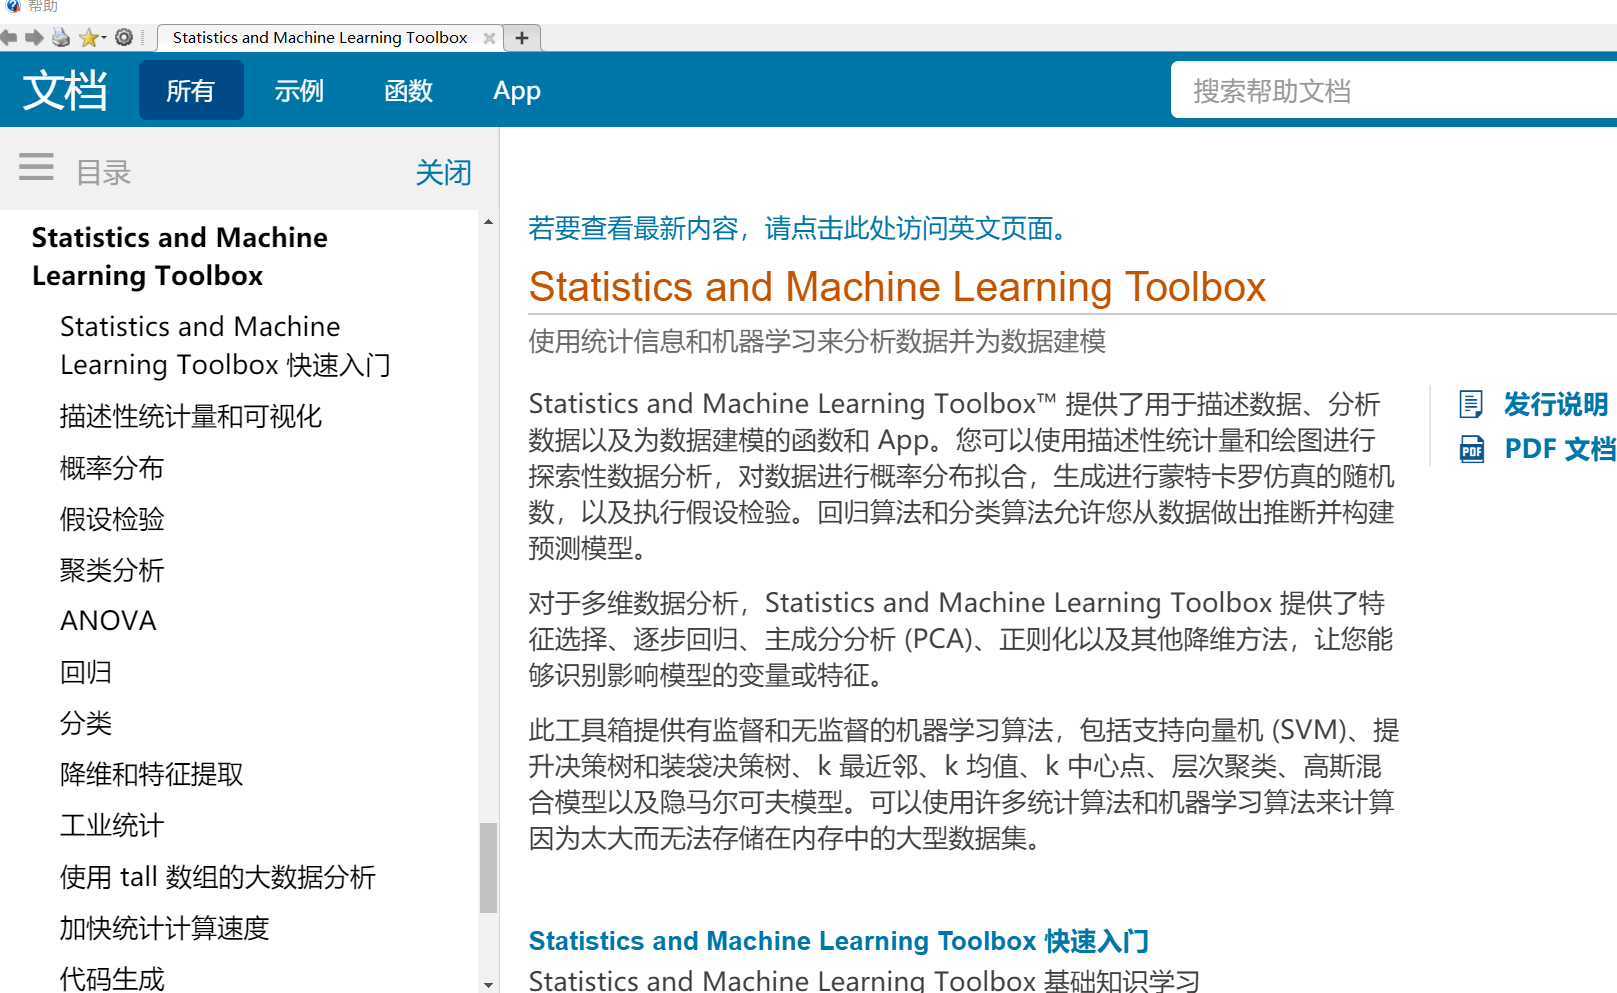

功能主要有，

- 统计指标和图表了解数据集；

- 拟合数据的概率分布；

- 生成随机数据；

- 假设检验

- 借助回归，分类算法，对数据集进行拟合并构建预测模型

- 对数据挖掘任务，提供了特征选择，逐步回归，主成分PCA，正则化和其他降维方法，用于重要变量和重要数据关系的挖掘。

- 工具箱还包括成熟的监督学习，非监督学习算法，如支持向量机，决策树，k近邻算法，层次聚类，隐马尔科夫模型

matlab中统计和线性代数：

机器学习是由统计学，概率论，计算机科学等诸多学科组成的交叉学科。

从原始数据集中进行迭代学习，寻找样本间隐藏的模式以及构建智能应用。

在home视图下，导入数据-->import  Data--> irisdata.csv 

导出：output  type

load matrix.txt
% 从txt文件中读入数据

读取 ; 号分隔的文件

MatrixTxt=dlmread('matrix.txt',',')

MatrixTxt =     10    20    30
    40    50    60
    70    80    90


导入文件中的前两行两列：

MatrixTxt2=dlmread('matrix.txt',',','A1..B2')

MatrixTxt2 =     10    20
    40    50


读取csv文件

MatrixCsv=csvread('matrix.csv') %逗号分隔的文件

MatrixCsv =     10    20    30
    40    50    60
    70    80    90


读excel工作表

xvalues = xlsread("capri.xlsx",'Temp') %第二个参数是工作表名称

xvalues =    1.000000000000000  26.000000000000000  24.000000000000000  29.000000000000000
   2.000000000000000  26.000000000000000  24.000000000000000  29.000000000000000
   3.000000000000000  26.000000000000000  24.000000000000000  30.000000000000000
   4.000000000000000  27.000000000000000  24.000000000000000  30.000000000000000
   5.000000000000000  26.000000000000000  23.000000000000000  28.000000000000000
   6.000000000000000  24.500000000000000  22.000000000000000  27.000000000000000
   7.000000000000000  27.000000000000000  23.000000000000000  31.000000000000000
   8.000000000000000  26.500000000000000  24.000000000000000  29.000000000000000
   9.000000000000000  26.500000000000000  24.000000000000000  29.000000000000000
  10.000000000000000  27.000000000000000  24.000000000000000  30.000000000000000


[values,headertext]=xlsread("capri.xlsx",'Temp') %读取表头文本

values =    1.000000000000000  26.000000000000000  24.000000000000000  29.000000000000000
   2.000000000000000  26.000000000000000  24.000000000000000  29.000000000000000
   3.000000000000000  26.000000000000000  24.000000000000000  30.000000000000000
   4.000000000000000  27.000000000000000  24.000000000000000  30.000000000000000
   5.000000000000000  26.000000000000000  23.000000000000000  28.000000000000000
   6.000000000000000  24.500000000000000  22.000000000000000  27.000000000000000
   7.000000000000000  27.000000000000000  23.000000000000000  31.000000000000000
   8.000000000000000  26.500000000000000  24.000000000000000  29.000000000000000
   9.000000000000000  26.500000000000000  24.000000000000000  29.000000000000000
  10.000000000000000  27.000000000000000  24.000000000000000  30.000000000000000


headertext = 1×4 cell 数组
    {'Day'}    {'TMean'}    {'Tmin'}    {'Tmax'}


headertext

headertext = 1×4 cell 数组
    {'Day'}    {'TMean'}    {'Tmin'}    {'Tmax'}


row1_2 = xlsread("capri.xlsx",'Temp','A2:D3') %读取前两行

row1_2 =      1    26    24    29
     2    26    24    29



column_C =xlsread("capri.xlsx",'Temp','C2:c6') %读取前两列

column_C =     24
    24
    24
    24
    23


### 读取混合型的数据

TableMuseum = readtable('museum.xls')

TableMuseum = 10×5 table
    N                     Museum                         City         Visitors_2016    Visitors_2015
    __    ______________________________________    ______________    _____________    _____________

     1    {'Colosseo e Foro Romano'            }    {'ROMA'      }       6408852          6551046   
     2    {'Scavi di Pompei'                   }    {'POMPEI'    }       3283740          2934010   
     3    {'Galleria degli Uffizi'             }    {'FIRENZE'   }       2010631          1971758   
     4    {'Galleria dell'Accademia di Firenze'}    {'FIRENZE'   }       1461185          1415397   
     5    {'Castel Sant'Angelo'                }    {'ROMA'      }       1234443          1047326   
     6    {'Venaria Reale'                     }    {'VENARIA R.'}       1012033           580786   
     7    {'Museo Egizio di Torino'            }    {'TORINO'    }        881463           863535   
     8    {'Circuito Museale Boboli …'         }    {'FIRENZE'   

TableMuseum1= readtable('museum.xls','ReadVariableNames',false)%不将列标题作为变量名

TableMuseum1 = 11×5 table
     Var1                      Var2                          Var3               Var4                 Var5       
    ______    ______________________________________    ______________    _________________    _________________

    {'N' }    {'Museum'                            }    {'City'      }    {'Visitors_2016'}    {'Visitors_2015'}
    {'1' }    {'Colosseo e Foro Romano'            }    {'ROMA'      }    {'6408852'      }    {'6551046'      }
    {'2' }    {'Scavi di Pompei'                   }    {'POMPEI'    }    {'3283740'      }    {'2934010'      }
    {'3' }    {'Galleria degli Uffizi'             }    {'FIRENZE'   }    {'2010631'      }    {'1971758'      }
    {'4' }    {'Galleria dell'Accademia di Firenze'}    {'FIRENZE'   }    {'1461185'      }    {'1415397'      }
    {'5' }    {'Castel Sant'Angelo'                }    {'ROMA'      }    {'1234443'      }    {'1047326'      }
    {'6' }    {'Venaria Reale'                     }    {'VENARIA R.'

能同时处理文本数据和数值数据的函数，textscan()

formatSpec ='%u%s%d%d';%数据字段的格式
fileID =fopen('Ferrari.txt');%包含5个最新的法拉利车型
Ferrari =textscan(fileID,formatSpec);
fclose(fileID);

ans =      0



whos Ferrari

  Name         Size            Bytes  Class    Attributes

  Ferrari      1x4              1222  cell               



Ferrari

Ferrari = 1×4 cell 数组
    {5×1 uint32}    {5×1 cell}    {5×1 int32}    {5×1 int32}


celldisp(Ferrari)%检查每一个条目

 
Ferrari{1} =
 
   2014
   2015
   2015
   2016
   2017

 
 
Ferrari{2}{1} =
 
Ferrari458SpecialeA
 
 
Ferrari{2}{2} =
 
Ferrari488GTB
 
 
Ferrari{2}{3} =
 
Ferrari488Spider
 
 
Ferrari{2}{4} =
 
FerrariJ50
 
 
Ferrari{2}{5} =
 
Ferrari812Superfast
 
 
Ferrari{3} =
 
   4497
   3902
   3902
   3902
   6496

 
 
Ferrari{4} =
 
   605
   670
   670
   690
   800

 


% 导出工作间所有内容供以后使用，扩展名为mat
%  save filename.mat

从matlab中导出数据

dlmwrite()函数

Mymatrix = rand(5)

Mymatrix =    0.814723686393179   0.097540404999410   0.157613081677548   0.141886338627215   0.655740699156587
   0.905791937075619   0.278498218867048   0.970592781760616   0.421761282626275   0.035711678574190
   0.126986816293506   0.546881519204984   0.957166948242946   0.915735525189067   0.849129305868777
   0.913375856139019   0.957506835434298   0.485375648722841   0.792207329559554   0.933993247757551
   0.632359246225410   0.964888535199277   0.800280468888800   0.959492426392903   0.678735154857773


dlmwrite('zhou.txt',Mymatrix) %把Mymatrix写到文本文件中，默认用逗号分隔
type('zhou.txt')


0.81472,0.09754,0.15761,0.14189,0.65574
0.90579,0.2785,0.97059,0.42176,0.035712
0.12699,0.54688,0.95717,0.91574,0.84913
0.91338,0.95751,0.48538,0.79221,0.93399
0.63236,0.96489,0.80028,0.95949,0.67874


也可以写到excel文件中

xlswrite('zhou.xls',Mymatrix)

写到csv文件中

csvwrite('zhou.csv',Mymatrix)


### 处理媒体文件

图像，音频，视频是人们生活中不可分割的一部分，在机器学习中也被作为输入数据，从中可以提取很多信息。

#### 处理图像数据

matlab中图像就是一个二维矩阵，每一个元素对应图像中的一个像素点，一个800X600像素的图像会被matlab存储为一个600*800的矩阵。有时还需要一个第三维来存储深度，比如，RGB图像，需要指定红绿蓝3个颜色通道值以构建一个彩色图像。

-  imread：从图形文件中读取图像；

- imwrite：将图像写入图形文件

- image：显示图像

- imfinfo：获取图像信息

- imagesc：归一化数据后显示图像

- ind2rgb：将索引图像转换为RGB图像

Coliseum = imread('coliseum.jpg'); %罗马斗兽场图片


导出图像

imwrite(Coliseum,'coliseum2.jpg');

显示图像

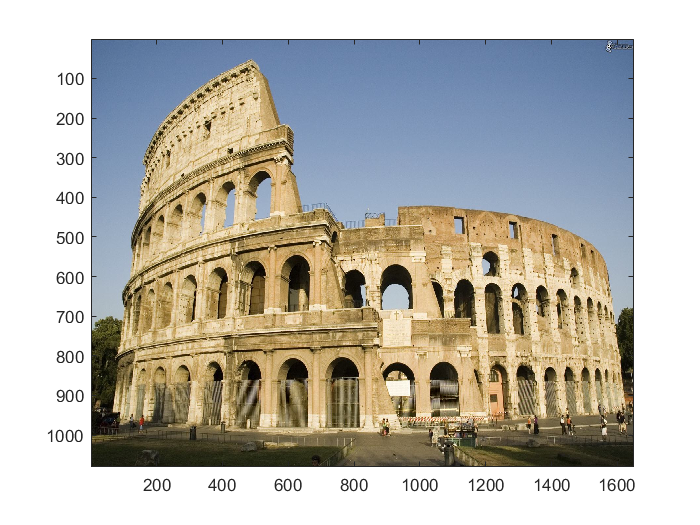

image(Coliseum)

音频文件处理

1.audioread() :读取音频文件

2. audioinfo：获取音频文件信息

3. audiowrite: 将数据写入音频

4. audioplayer:创建音频播放对象

5.audiorecorder：创建音频录制对象

6. sound：将信号数据转为声音

7. beep：蜂鸣

[apollo13,Fs] = audioread('apollo.wav');%休斯敦，我们有麻烦了
% apollo13为音频数据矩阵，Fs采样率


播放

% sound(apollo13,Fs)


若要控制播放过程，需要定义回调函数，创一个audioplayer对象，调用这个对象的方法去播放音频：

Apollo13Obj = audioplayer(apollo13,Fs);
play(Apollo13Obj);


导出音频：

audiowrite('apollo13.wav',apollo13,Fs)
InfoAudio = audioinfo('apollo13.wav') % 音频信息


matlab中的table类型

用来将混合型的数据和元数据(变量名，行名)收集到单个容器中，适合表格型数据以列形式存储在文本文件或电子表格中。

一个病人的数据：

load hospital %原始文件为hospital.mat文件，

  Name                    Size                  Bytes  Class          Attributes

  Age                   100x1                     800  double                   
  AgeC                  100x1                    3002  categorical              
  Apollo13Obj             1x1                       8  audioplayer              
  BlPrMax               100x1                     800  double                   
  BlPrMin               100x1                     800  double                   
  Coliseum             1080x1650x3            5346000  uint8                    
  Description             1x23                     46  char                     
  Ferrari                 1x4                    1222  cell                     
  Fs                      1x1                       8  double                   
  LastName              100x1                   12416  cell                     
  MatrixCsv               3x3                      72  double                   
  MatrixTxt               3

% 也可以用readtable()从电子表格或文本文件中创建table

whos
LastName=hospital.LastName;
Sex=hospital.Sex;
Age=hospital.Age;
Weight=hospital.Weight;


ans = 5×4 table
      LastName       Sex      Age    Weight
    ____________    ______    ___    ______

    {'SMITH'   }    Male      38      176  
    {'JOHNSON' }    Male      43      163  
    {'WILLIAMS'}    Female    38      131  
    {'JONES'   }    Female    40      133  
    {'BROWN'   }    Female    49      119  


下面创建一个表格，填充之前提取出来的数据：

TablePatients = table(LastName,Sex,Age,Weight);
TablePatients(1:5,:) %显示1到5行

从开始的数据集中提取血压：

BlPrMax=hospital.BloodPressure(:,1);
BlPrMin=hospital.BloodPressure(:,2);

这两个新变量添加到table中

TablePatients.BlPrMax=BlPrMax;

ans = 5×3 table
      LastName      BlPrMax    BlPrMin
    ____________    _______    _______

    {'SMITH'   }      124        93   
    {'JOHNSON' }      109        77   
    {'WILLIAMS'}      125        83   
    {'JONES'   }      117        75   
    {'BROWN'   }      122        80   


TablePatients.BlPrMin=BlPrMin; 

确认刚才的操作：

TablePatients(1:5,[1 5:6])


Variables:

    LastName: 100×1 cell array of character vectors

    Sex: 100×1 categorical

        Values:

            Female     53  
            Male       47  

    Age: 100×1 double

        Values:

            Min        25  
            Median     39  
            Max        50  

    Weight: 100×1 double

        Values:

            Min          111  
            Median     142.5  
            Max          202  

    BlPrMax: 100×1 double

        Values:

            Min          109   
            Median       122   
            Max          138   

    BlPrMin: 100×1 double

        Values:

            Min           68   
            Median      81.5   
            Max           99   



查看汇总信息：

summary(TablePatients)

### 分类数组

无序分类（男，女）

有序分类（1，2，3，4）

categorical函数从一个数值数组，逻辑数组，元胞数组，字符数组或者一个已经存在的分类数组中创建分类数组

SexC=categorical(Sex);

ans = 2×1 cell 数组
    {'Female'}
    {'Male'  }


categories(SexC)

有序分类数组

AgeC=categorical(Age);
categories(AgeC)

ans = 25×1 cell 数组
    {'25'}
    {'27'}
    {'28'}
    {'29'}
    {'30'}
    {'31'}
    {'32'}
    {'33'}
    {'34'}
    {'35'}
    {'36'}
    {'37'}
    {'38'}
    {'39'}
    {'40'}
    {'41'}
    {'42'}
    {'43'}
    {'44'}
    {'45'}
    {'46'}
    {'47'}
    {'48'}
    {'49'}
    {'50'}


从分箱后的数值型数据中创建一个有序分类数组。原始数据经过分箱后分别落入给定的区间，区间的代表值为中心值。用discretize函数对age变量进行分箱，分三个年龄段(25~33,33~41,41~50,包含左端点，不包含右端点)：

NameBin = {'FirstBin', 'SecondBin', 'ThirdBin'};
AgeBin = discretize(Age,[25 33 41 50],'categorical',NameBin);
summary(AgeBin)%统计每个区间上的数量

     FirstBin       27 
     SecondBin      33 
     ThirdBin       40 


## 数据挖掘

清洗数据，缺失值插补，异常值，添加派生数据，描述性统计方法

### 一、区分变量类别

- 定量变量：温度，压强，湿度 

   又分  定距变量：基于差的结果

             定比变量：

       2. 定性变量：分类变量，非数值型变量，无计量单位

  定类变量：如血型，不能运算

 二分变量：定类特例，只有两种类型，如性别

定序变量：

### 二、数据准备

data wrangling占80%的时间，数据整理

Edgar F. Codd建议，如果一个数据集满足：

- 每行是观测结果

- 每列是观测变量

- 数据是在单一的数据集中

则称这个数据集是干净的。

例：有问题的表格CleaningData.xlsx数据

% cd('目录名')
SampleData = readtable('CleaningData.xlsx');
summary(SampleData)


Variables:

    name: 12×1 cell array of character vectors

    gender: 12×1 cell array of character vectors

    age: 12×1 cell array of character vectors

    right: 12×1 cell array of character vectors

    wrong: 12×1 double

        Values:

            Min          2   
            Median      43   
            Max         95   



SampleData

SampleData = 12×5 table
        name          gender        age       right     wrong
    ____________    __________    _______    _______    _____

    {'Emma'    }    {'F'     }    {'24' }    {'80' }     20  
    {'Liam'    }    {'M'     }    {'-19'}    {'.'  }     47  
    {'Olivia'  }    {0×0 char}    {'32' }    {'75' }     25  
    {'Noah'    }    {'M'     }    {'15' }    {'60' }     40  
    {'Ava'     }    {'F'     }    {'18' }    {'45' }     55  
    {'Mason'   }    {'M'     }    {'21' }    {'54' }     46  
    {'Isabella'}    {'F'     }    {'28' }    {'-19'}     85  
    {'Lucas'   }    {'M'     }    {'30' }    {'13' }     87  
    {'Sophia'  }    {'F'     }    {'26' }    {'NaN'}     30  
    {'Elijah'  }    {'M'     }    {'100'}    {'98' }      2  
    {'Mia'     }    {'F'     }    {'22' }    {'5'  }     95  
    {'Oliver'  }    {'M'     }    {'NA' }    {'NaN'}     21  


其中有缺失值NA，无效值NAN

使用函数ismissing()快速找到包含缺失值的观测结果。

%Find missing values
id = {'NA' '' '-19' -19 NaN '.'};
WrongPos = ismissing(SampleData,id); %逻辑数组，缺失值的位置
SampleData(any(WrongPos,2),:) %缺失值的记录

ans = 4×5 table
        name          gender        age       right     wrong
    ____________    __________    _______    _______    _____

    {'Liam'    }    {'M'     }    {'-19'}    {'.'  }     47  
    {'Olivia'  }    {0×0 char}    {'32' }    {'75' }     25  
    {'Isabella'}    {'F'     }    {'28' }    {'-19'}     85  
    {'Oliver'  }    {'M'     }    {'NA' }    {'NaN'}     21  


对不同的数据类类型有不同的默认缺失值指示符，数值型的NaN，字符型为'',，分类数组为<undefined>

### 改变数据类型

%Change data type
SampleData.age = str2double(SampleData.age);
summary(SampleData(:,3))


Variables:

    age: 12×1 double

        Values:

            Min             -19  
            Median          24   
            Max             100  
            NumMissing      1    



把age转为数值型的。

SampleData.right = str2double(SampleData.right);
summary(SampleData(:,4))


Variables:

    right: 12×1 double

        Values:

            Min             -19  
            Median          54   
            Max             98   
            NumMissing      3    



### 替换缺失值

%Replace missing value
SampleData = standardizeMissing(SampleData,-19);
summary(SampleData(:,3))


Variables:

    age: 12×1 double

        Values:

            Min             15   
            Median          25   
            Max             100  
            NumMissing      2    



-19换成了NaN，缺失值数量改变为2

用前一行数据替换缺失值：

SampleDataNew = fillmissing(SampleData,'previous')

SampleDataNew = 12×5 table
        name        gender    age    right    wrong
    ____________    ______    ___    _____    _____

    {'Emma'    }    {'F'}      24     80       20  
    {'Liam'    }    {'M'}      24     80       47  
    {'Olivia'  }    {'M'}      32     75       25  
    {'Noah'    }    {'M'}      15     60       40  
    {'Ava'     }    {'F'}      18     45       55  
    {'Mason'   }    {'M'}      21     54       46  
    {'Isabella'}    {'F'}      28     54       85  
    {'Lucas'   }    {'M'}      30     13       87  
    {'Sophia'  }    {'F'}      26     13       30  
    {'Elijah'  }    {'M'}     100     98        2  
    {'Mia'     }    {'F'}      22      5       95  
    {'Oliver'  }    {'M'}      22      5       21  


移除缺失值

%Removing missing entries
SampleDataMinor = rmmissing(SampleData)

SampleDataMinor = 7×5 table
       name       gender    age    right    wrong
    __________    ______    ___    _____    _____

    {'Emma'  }    {'F'}      24     80       20  
    {'Noah'  }    {'M'}      15     60       40  
    {'Ava'   }    {'F'}      18     45       55  
    {'Mason' }    {'M'}      21     54       46  
    {'Lucas' }    {'M'}      30     13       87  
    {'Elijah'}    {'M'}     100     98        2  
    {'Mia'   }    {'F'}      22      5       95  


为表格排序

%按年龄降序排列

%Ordering the table
SampleDataOrdered = sortrows(SampleDataMinor,{'age'},{'descend'})

SampleDataOrdered = 7×5 table
       name       gender    age    right    wrong
    __________    ______    ___    _____    _____

    {'Elijah'}    {'M'}     100     98        2  
    {'Lucas' }    {'M'}      30     13       87  
    {'Emma'  }    {'F'}      24     80       20  
    {'Mia'   }    {'F'}      22      5       95  
    {'Mason' }    {'M'}      21     54       46  
    {'Ava'   }    {'F'}      18     45       55  
    {'Noah'  }    {'M'}      15     60       40  


找异常值

%Find outliers in data
SampleDataOutlier = isoutlier(SampleDataNew(2:end,3:5))

SampleDataOutlier = 11×3 logical 数组
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   1   0   0
   0   0   0


默认，找到的离群值是指与中位数相差超过3倍经过换算的绝对中位差的值，分别作用到3个数值列。

将多个数据源合并称一个数据源

%Organizing 
SampleData1 = SampleDataNew(1:6,:)

SampleData1 = 6×5 table
       name       gender    age    right    wrong
    __________    ______    ___    _____    _____

    {'Emma'  }    {'F'}     24      80       20  
    {'Liam'  }    {'M'}     24      80       47  
    {'Olivia'}    {'M'}     32      75       25  
    {'Noah'  }    {'M'}     15      60       40  
    {'Ava'   }    {'F'}     18      45       55  
    {'Mason' }    {'M'}     21      54       46  


SampleData2 = SampleDataNew(7:12,:)

SampleData2 = 6×5 table
        name        gender    age    right    wrong
    ____________    ______    ___    _____    _____

    {'Isabella'}    {'F'}      28     54       85  
    {'Lucas'   }    {'M'}      30     13       87  
    {'Sophia'  }    {'F'}      26     13       30  
    {'Elijah'  }    {'M'}     100     98        2  
    {'Mia'     }    {'F'}      22      5       95  
    {'Oliver'  }    {'M'}      22      5       21  


SampleDataComplete = [SampleData1;SampleData2]

SampleDataComplete = 12×5 table
        name        gender    age    right    wrong
    ____________    ______    ___    _____    _____

    {'Emma'    }    {'F'}      24     80       20  
    {'Liam'    }    {'M'}      24     80       47  
    {'Olivia'  }    {'M'}      32     75       25  
    {'Noah'    }    {'M'}      15     60       40  
    {'Ava'     }    {'F'}      18     45       55  
    {'Mason'   }    {'M'}      21     54       46  
    {'Isabella'}    {'F'}      28     54       85  
    {'Lucas'   }    {'M'}      30     13       87  
    {'Sophia'  }    {'F'}      26     13       30  
    {'Elijah'  }    {'M'}     100     98        2  
    {'Mia'     }    {'F'}      22      5       95  
    {'Oliver'  }    {'M'}      22      5       21  


%[]串联数组


join函数添加一些特征数据

LifeExpectancy = readtable('LifeExpectancy.xlsx')

LifeExpectancy = 2×3 table
        state         Le      gender
    _____________    _____    ______

    {'Hong Kong'}    80.91    {'M'} 
    {'Hong Kong'}    86.58    {'F'} 


SampleDataLE = join(SampleDataComplete,LifeExpectancy,'Keys','gender')

SampleDataLE = 12×7 table
        name        gender    age    right    wrong        state         Le  
    ____________    ______    ___    _____    _____    _____________    _____

    {'Emma'    }    {'F'}      24     80       20      {'Hong Kong'}    86.58
    {'Liam'    }    {'M'}      24     80       47      {'Hong Kong'}    80.91
    {'Olivia'  }    {'M'}      32     75       25      {'Hong Kong'}    80.91
    {'Noah'    }    {'M'}      15     60       40      {'Hong Kong'}    80.91
    {'Ava'     }    {'F'}      18     45       55      {'Hong Kong'}    86.58
    {'Mason'   }    {'M'}      21     54       46      {'Hong Kong'}    80.91
    {'Isabella'}    {'F'}      28     54       85      {'Hong Kong'}    86.58
    {'Lucas'   }    {'M'}      30     13       87      {'Hong Kong'}    80.91
    {'Sophia'  }    {'F'}      26     13       30      {'Hong Kong'}    86.58
    {'Elijah'  }    {'M'}     100     98        2      {'Hong Kong'}    80.91
    {'Mia'     }    {'F'}      22    

% join函数使用键变量按行合并两个表

## 探索性数据发现

一、位置测量

中心数据

GlassIdentificationDataSet = readtable('GlassIdentificationDataSet.xlsx');
%214行，11个变量的数据集，氧化物含量

统计第3列到第8列对应的氧化物含量

Max = max(GlassIdentificationDataSet{:,3:8})

Max =   17.379999999999999   4.490000000000000   3.500000000000000  75.409999999999997   6.210000000000000  16.190000000000001


Mean = mean(GlassIdentificationDataSet{:,3:8})

Mean =   13.407850467289723   2.684532710280374   1.444906542056075  72.650934579439252   0.497056074766355   8.956962616822430


Min = min(GlassIdentificationDataSet{:,3:8})

Min =   10.730000000000000                   0   0.290000000000000  69.810000000000002                   0   5.430000000000000


找到最小，最大值分别对应哪一行记录

[Max,IndRowMax] = max(GlassIdentificationDataSet{:,3:8})

Max =   17.379999999999999   4.490000000000000   3.500000000000000  75.409999999999997   6.210000000000000  16.190000000000001


IndRowMax =    185     1   164   185   172   108


[Min,IndRowMin] = min(GlassIdentificationDataSet{:,3:8})

Min =   10.730000000000000                   0   0.290000000000000  69.810000000000002                   0   5.430000000000000


IndRowMin =    107   106    22   107    64   186


中位数，众数

Median = median(GlassIdentificationDataSet{:,3:8})

Median =   13.300000000000001   3.480000000000000   1.360000000000000  72.790000000000006   0.555000000000000   8.600000000000000


Mode = mode(GlassIdentificationDataSet{:,3:8})

Mode =   13.000000000000000                   0   1.540000000000000  72.859999999999999                   0   8.029999999999999


分位数，百分位数：

Quantile = quantile(GlassIdentificationDataSet{:,3:8}, [0.25 0.50 0.75])

Quantile =   12.900000000000000   2.090000000000000   1.190000000000000  72.280000000000001   0.120000000000000   8.240000000000000
  13.300000000000001   3.480000000000000   1.360000000000000  72.790000000000006   0.555000000000000   8.600000000000000
  13.830000000000000   3.600000000000000   1.630000000000000  73.090000000000003   0.610000000000000   9.180000000000000


Percentiles = prctile(GlassIdentificationDataSet{:,3:8}, [25 50 75])

Percentiles =   12.900000000000000   2.090000000000000   1.190000000000000  72.280000000000001   0.120000000000000   8.240000000000000
  13.300000000000001   3.480000000000000   1.360000000000000  72.790000000000006   0.555000000000000   8.600000000000000
  13.830000000000000   3.600000000000000   1.630000000000000  73.090000000000003   0.610000000000000   9.180000000000000


二、分散度测量

% 极差
Range = range(GlassIdentificationDataSet{:,3:8})

Range =    6.649999999999999   4.490000000000000   3.210000000000000   5.599999999999994   6.210000000000000  10.760000000000002


 % 方差，标准差（逐列计算）
Variance = var(GlassIdentificationDataSet{:,3:8})

Variance =    0.666841367206353   2.080540390943791   0.249270179018033   0.599921188188320   0.425354203413629   2.025365848361194


StDev = std(GlassIdentificationDataSet{:,3:8})

StDev =    0.816603555714983   1.442407844870441   0.499269645600485   0.774545794765112   0.652191845558980   1.423153487281394


Mad = mad(GlassIdentificationDataSet{:,3:8})

Mad =    0.598897720324920   1.209406498384137   0.359052318979824   0.555695693947070   0.294362826447725   0.918126910647219


量化两组数据随时间变化的趋势，相关性和协方差

a=[1 2 3 4]

a =      1     2     3     4


b=10*a

b =     10    20    30    40


c=fliplr(a)

c =      4     3     2     1


d=randperm(4,4)

d =      2     1     4     3


MatA =[a' b' c' d']

MatA =      1    10     4     2
     2    20     3     1
     3    30     2     4
     4    40     1     3


CovMatA=cov(MatA)

CovMatA = 	1.0e+02 *

   0.016666666666667   0.166666666666667  -0.016666666666667   0.010000000000000
   0.166666666666667   1.666666666666667  -0.166666666666667   0.100000000000000
  -0.016666666666667  -0.166666666666667   0.016666666666667  -0.010000000000000
   0.010000000000000   0.100000000000000  -0.010000000000000   0.016666666666667


上面案例中，a,b正相关，a,c负相关，a,d无任何联系

协方差矩阵，每列两两组合计算处的协方差，正代表这两个随机变量正在往相同方向移动，负则表示向相反反向移动。

MatA =rand(4)

MatA =    0.162611735194631   0.340385726666133   0.255095115459269   0.959291425205444
   0.118997681558377   0.585267750979777   0.505957051665142   0.547215529963803
   0.498364051982143   0.223811939491137   0.699076722656686   0.138624442828679
   0.959743958516081   0.751267059305653   0.890903252535798   0.149294005559057


Cov = cov(MatA)

Cov =    0.151141345728348   0.043625237367078   0.094196666789929  -0.115656468373115
   0.043625237367078   0.056566258386835   0.030516093086239  -0.020899491652897
   0.094196666789929   0.030516093086239   0.073881630682782  -0.101064733613644
  -0.115656468373115  -0.020899491652897  -0.101064733613644   0.152066559573009


相关系数

MatB = rand(3)

MatB =    0.257508254123736   0.814284826068816   0.349983765984809
   0.840717255983663   0.243524968724989   0.196595250431208
   0.254282178971531   0.929263623187228   0.251083857976031


Cor = corrcoef(MatB)

Cor =    1.000000000000000  -0.988407979871921  -0.768688885133065
  -0.988407979871921   1.000000000000000   0.662669942670981
  -0.768688885133065   0.662669942670981   1.000000000000000


 分布形状测量

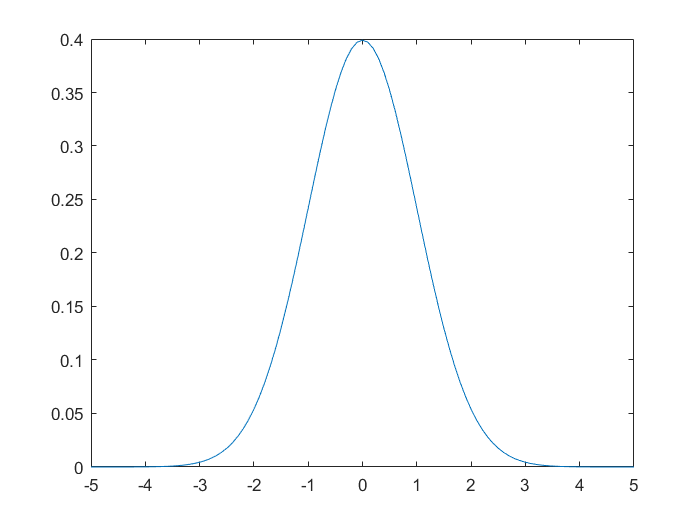

a = [-5:.1:5];
Norm = normpdf(a,0,1); %正态分布
figure;
plot(a,Norm) 

偏度：正偏/左偏；负偏/右偏

正态分布偏度为0.

GlassIdentificationDataSet=readtable('GlassIdentificationDataSet.xlsx')

GlassIdentificationDataSet = 214×11 table
    Id      RI       Na       Mg      Al      Si       K       Ca     Ba     Fe     Type
    __    ______    _____    ____    ____    _____    ____    ____    __    ____    ____

     1    152101    13.64    4.49     1.1    71.78    0.06    8.75    0        0     1  
     2    151761    13.89     3.6    1.36    72.73    0.48    7.83    0        0     1  
     3    151618    13.53    3.55    1.54    72.99    0.39    7.78    0        0     1  
     4    151766    13.21    3.69    1.29    72.61    0.57    8.22    0        0     1  
     5    151742    13.27    3.62    1.24    73.08    0.55    8.07    0        0     1  
     6    151596    12.79    3.61    1.62    72.97    0.64    8.07    0     0.26     1  
     7    151743     13.3     3.6    1.14    73.09    0.58    8.17    0        0     1  
     8    151756    13.15    3.61    1.05    73.24    0.57    8.24    0        0     1  
     9    151918    14.04    3.58    1.37    72.08    0.56     8.3 

SkN = skewness(GlassIdentificationDataSet{:,3:8})

SkN =    0.450991720011593  -1.144464849598671   0.900917878142526  -0.725317266451323   6.505635834012879   2.032677375526250


峰度，kurtos，驼峰的意思，正态分布峰度为3

Kurt = kurtosis(GlassIdentificationDataSet{:,3:8})

Kurt =    5.953476583500215   2.571298442011893   4.984831774623821   5.871104597145355  56.392326556204630   9.498967959876072


### 探索性可视化

一元图形探索单变量的分布，箱型图，柱状图

二元图形展示两个变量之间的关系，如分组散点图，二元柱状图

标注图中的点，添加最小二乘回归直线

EmergencyCalls = xlsread('EmergencyCalls.xlsx');
[rows,cols] = size(EmergencyCalls);
x = 1:rows;
plot(x,EmergencyCalls)
legend('Street 1','Street 2','Street 3','Street 4')
xlabel('Time')
ylabel('Emergency Calls')

24小时，不同街道的电话呼叫次数，四个街区数据，每个数据集指代矩阵中的每一列。

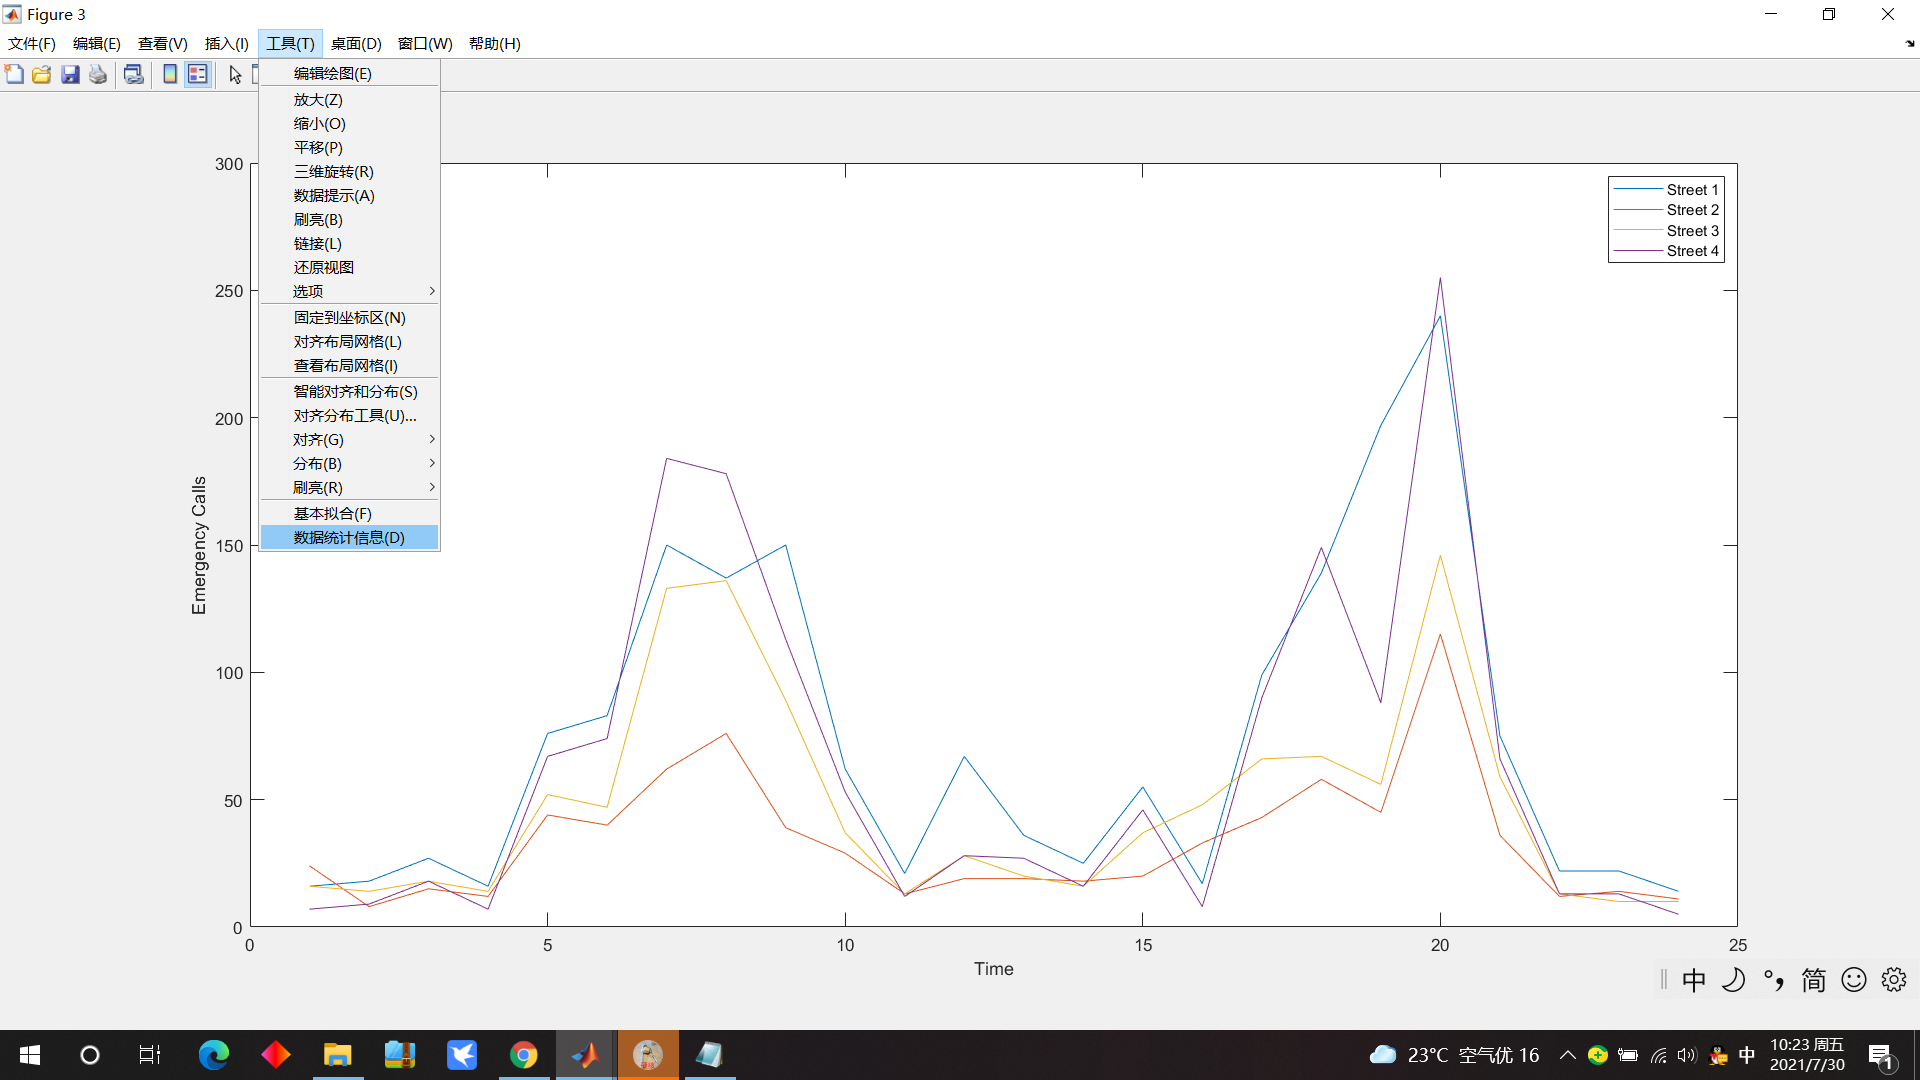

在图像窗口选择tools/dataStatistics可看到X轴和Y轴变量的描述性统计信息。

点窗口工具栏中箭头按钮，双击图形中所要修改的那根线，就会在图形窗口下方弹出属性编辑对话框。

可以把统计分析信息保存到工作间。

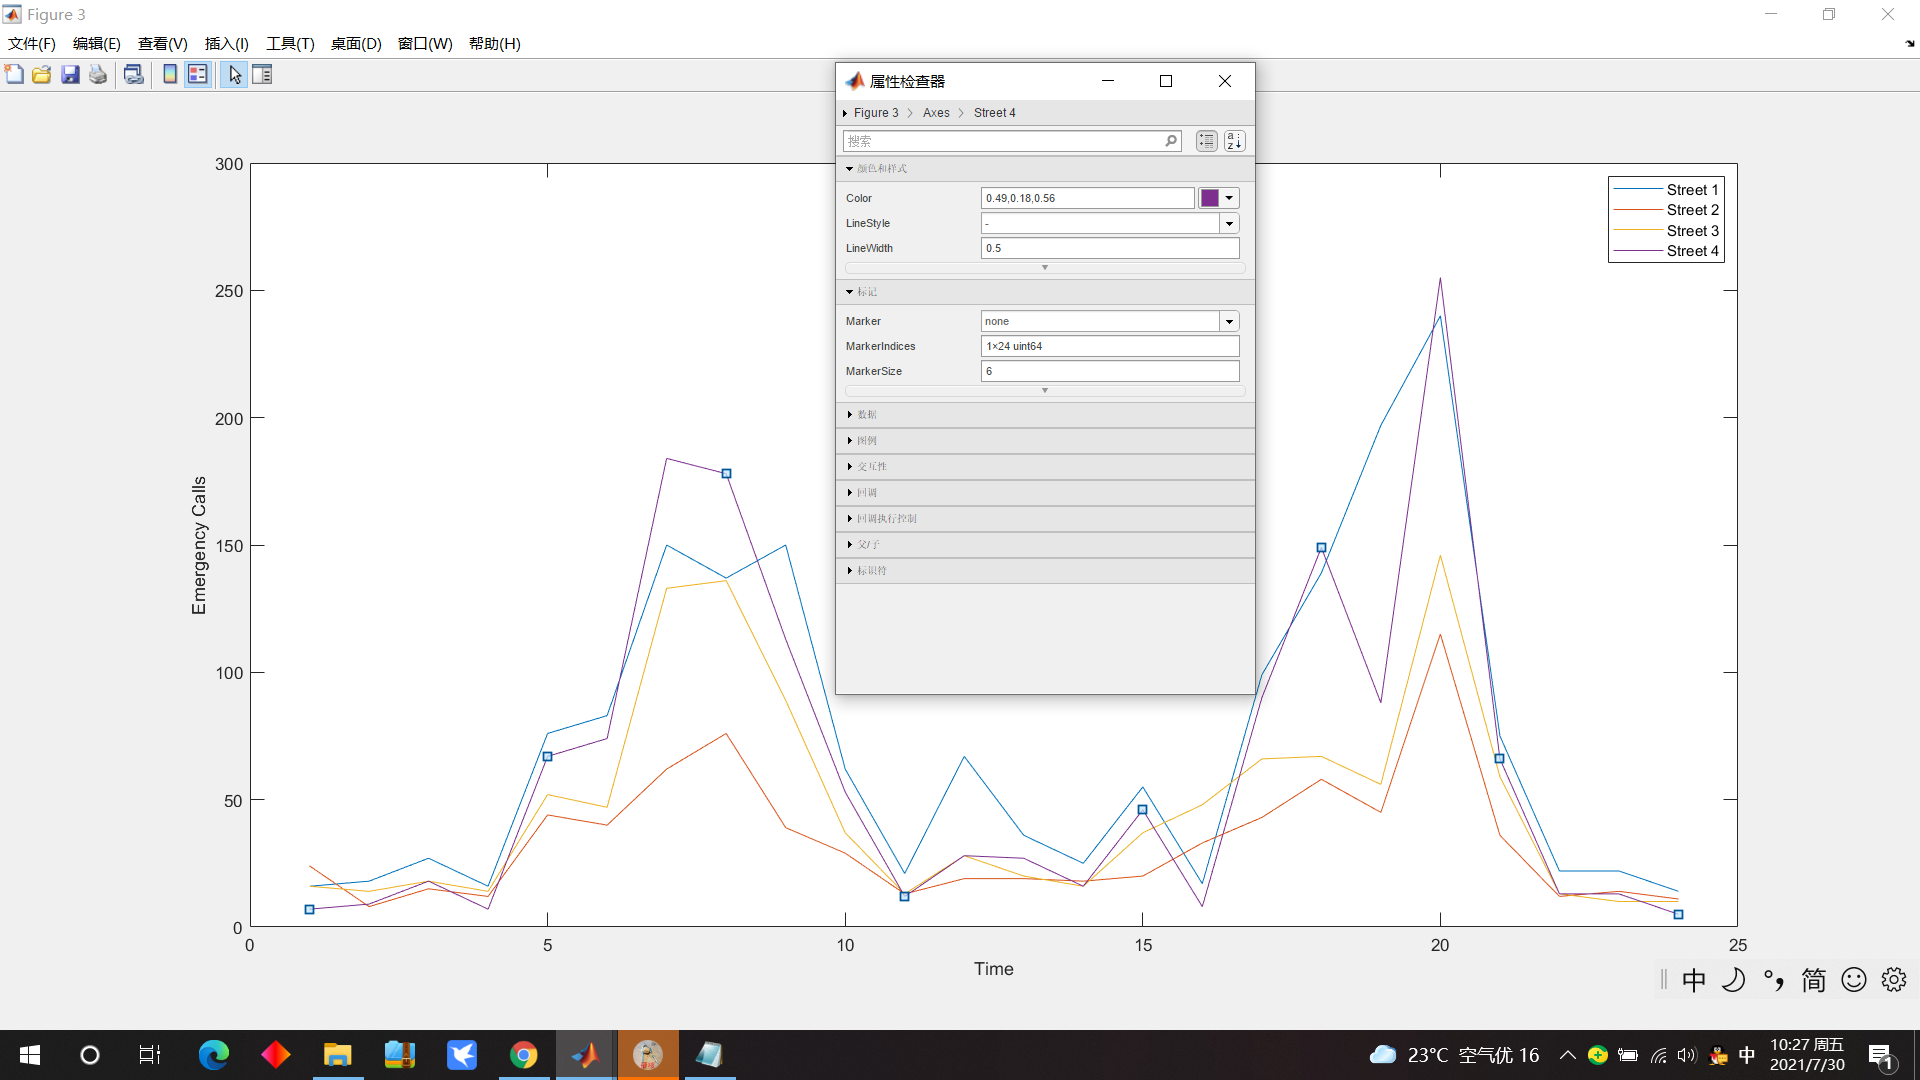

柱状图

Vect1=[10,25,12,13,33,25,44,50,43,26,38,32,31,28,30];
histogram(Vect1) %自动均分分箱
Vect2=[10,25,12,13,33,25,44,50,43,26,38,32,31,28,30,15,16,22,35,18];
h = histogram(Vect2,12)

h =   Histogram - 属性:

             Data: [10 25 12 13 33 25 44 50 43 26 38 32 31 28 30 15 16 22 35 18]
           Values: [2 2 2 1 3 1 4 1 1 1 1 1]
          NumBins: 12
         BinEdges: [9 12.500000000000000 16 19.500000000000000 23 26.500000000000000 30 33.500000000000000 37 40.500000000000000 44 47.500000000000000 51]
         BinWidth: 3.500000000000000
        BinLimits: [9 51]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性


Vect4 = randn(1000,1);
h = histogram(Vect4,'Normalization','pdf')  %画出概率密度图

h =   Histogram - 属性:

             Data: [1000×1 double]
           Values: [1×21 double]
          NumBins: 21
         BinEdges: [1×22 double]
         BinWidth: 0.300000000000000
        BinLimits: [-3.300000000000001 3]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性


Vect5 = normrnd(50,3,1000,1);
Hist = histfit(Vect5) %画出拟合曲线

Hist =   2×1 graphics 数组:

  Bar
  Line


散点图

Height = [168  168	168	173	163	174	174	174	175	175	176	165	180	180	182	182	183	186	191	191	192	165	167	174	176	167];
Weight = [65	 65	65	78	70	68	68	80	70	75	77	69	80	65	79	79	79	80	81	81	82	69	69	77	68	70];
scatter(Weight,Height)
IdealWeight=Height-100-[(Height-150)/4];
hold on
plot(IdealWeight,Height) %理想体重线

变量很多时，用散点图矩阵

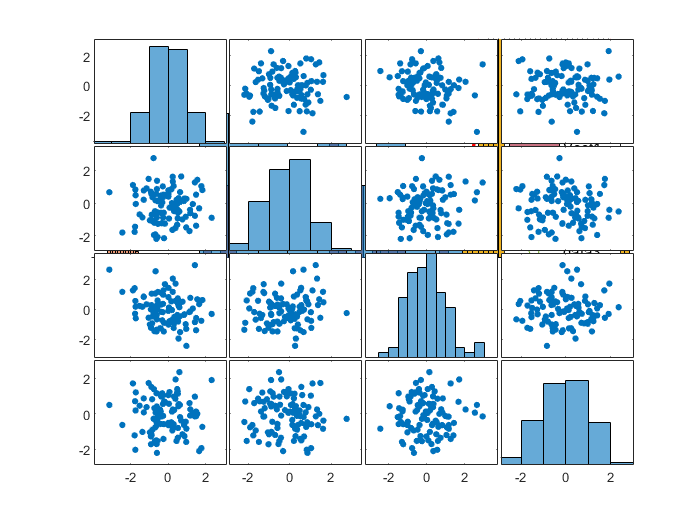

RandomMatrix = randn(100,4);
plotmatrix(RandomMatrix)

参考文献

- [意]朱塞佩.恰布罗，张雅仁等译，人民邮电出版社，matlab机器学习，2020年5月